# Assignment 1

## Let's assume we obtained the class conditional probability of salmon and sea bass, describing the distribution of the length of the two classes. These are given by p_salmon and p_seabass at length l (in cm), all in the file lab3 1.mat.

First lets see what the data we're given is:

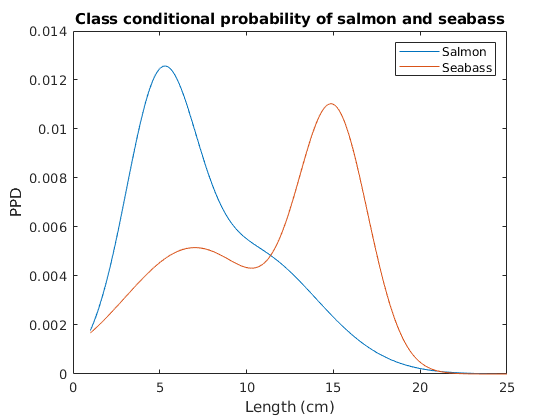

plot(l, p_salmon)
hold on
plot(l, p_seabass)
title('Class conditional probability of salmon and seabass')
legend('Salmon', 'Seabass')
xlabel('Length (cm)')
ylabel('PPD')
hold off

So, what we're given is the class conditional probability density function of both salmon and sea bass, that means p(x|wi)

1. Given that sea bass is caught 3 times as often as salmon, calculate the posterior probabilities (don't forget to normalize to 1 for all lengths) and plot them.

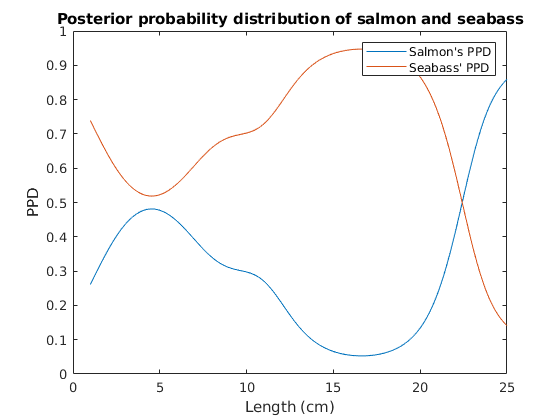

prior_salmon = 1/4;
prior_seabass = 3/4;

% Calculate the evidence (p(x))
evidence = prior_salmon*p_salmon + prior_seabass*p_seabass;

% Calculate the posterior distribution for both fishes

posterior_salmon = prior_salmon.*p_salmon./evidence;
posterior_seabass = prior_seabass.*p_seabass./evidence;

% Plot the posterior probability distributions
plot(l, posterior_salmon)
hold on
plot(l, posterior_seabass)
title('Posterior probability distribution of salmon and seabass')
legend("Salmon's PPD", "Seabass' PPD")
xlabel('Length (cm)')
ylabel('PPD')

2. Now a new fish is measured, which turns out to have a length of 8 cm. According to your posterior probabilities, how would you classify this fish? And what if it's length is 20 cm?

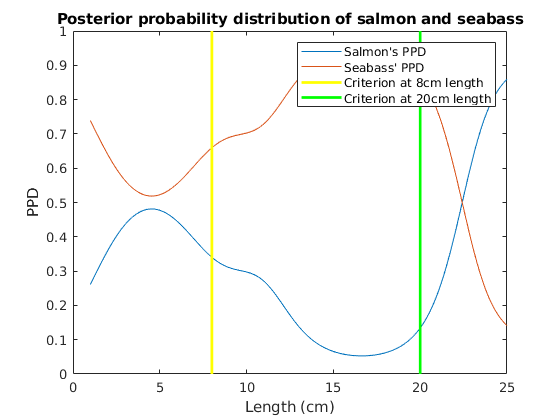

% 8cm fish
% Add a line to the plot to have a graphic idea
line([8, 8], ylim, 'LineWidth', 2, 'Color', 'y')
% Find the index in the length array for 8cm
index = find(l ==8);
% Find the posterior probability for both salmon and seabass at 8cm
prob_salmon1 = posterior_salmon(index);
prob_seabass1 = posterior_seabass(index);

% 20cm fish
% Add a line to the plot to have a graphic idea
line([20, 20], ylim, 'LineWidth', 2, 'Color', 'g')
legend("Salmon's PPD", "Seabass' PPD", "Criterion at 8cm length", "Criterion at 20cm length")

% Find the index in the length array for 20cm
index = find(l ==20);
% Find the posterior probability for both salmon and seabass at 20cm
prob_salmon2 = posterior_salmon(index);
prob_seabass2 = posterior_seabass(index);

% Results
fprintf('Case 8cm long fish:')

Case 8cm long fish:

fprintf('Posterior probability for salmon: %.4f', prob_salmon1)

Posterior probability for salmon: 0.3403

fprintf('Posterior probability for seabass: %.4f', prob_seabass1)

Posterior probability for seabass: 0.6597

fprintf('Case 20cm long fish:')

Case 20cm long fish:

fprintf('Posterior probability for salmon: %.4f', prob_salmon2)

Posterior probability for salmon: 0.1342

fprintf('Posterior probability for seabass: %.4f', prob_seabass2)

Posterior probability for seabass: 0.8658

For a fish 8cm long, given that the posterior probability for seabass is greater than the one for salmon, we would classify this fish as seabass.

For a fish 20cm long, the posterior probability for seabass is also greater than the on for salmon, so we would also classify this fish as seabass.